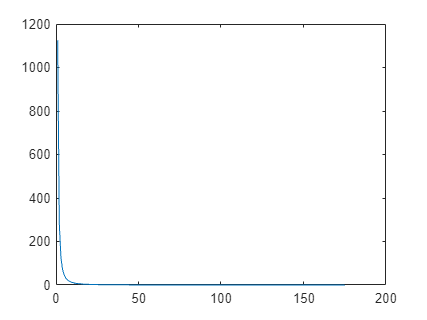

% Solve for C_Lopt
clc
clear all

e = 1;
r = 0:175; % Turn radius m
A = 22.82;%linspace(10,60,length(r)); % Aspect Ratio
rho = 1.0834; % Density at a+*lt
g = 9.81; % Accel due to gravity m/S^2
W2S = 450;%linspace(250:550,length(r)); % Wing Loading N/m^2
W2S = 280; % to mathc figure 89
L_Dmax = 22.82;

C_L_max = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
C_D_max = 2 * (C_L_max^2)/(pi * A * e); % Maximum drag coefficient
C_D_0 = C_D_max / 2; % Parasite drag coefficient


V_T = HorstmannThermal(r);
V_sc = Vsinkrate(C_D_max, C_L_max, r, g, rho, W2S);
V_sc = SinkRateCircle(C_L_max, C_D_0, A, e, W2S, rho, r);

% compute climb speed from thermal updraft speed and aircraft sink rate
V_c = V_T + V_sc; % climb speed (m/s)

% debugging
plot(r, ( 2*W2S ./ (rho*r.*g*C_L_max) ).^2)

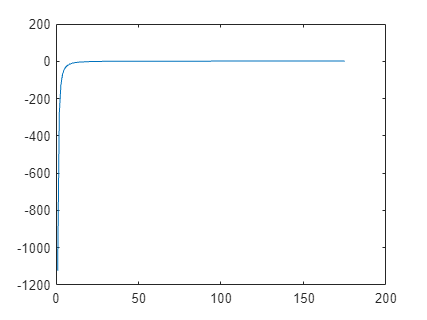

plot(r, 1 - ( 2*W2S ./ (rho*r.*g*C_L_max) ).^2 )

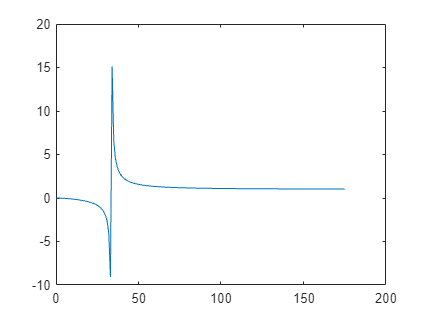

plot(r, ( 1 - ( 2*W2S ./ (rho*r.*g*C_L_max) ).^2 ).^(-3/4))

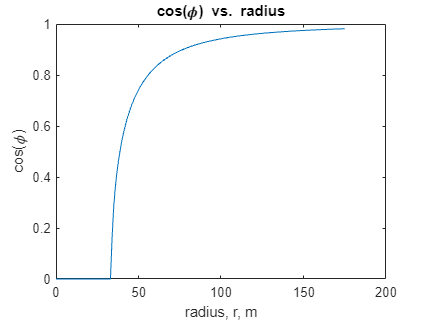


% plot cos phi as a function of radius
cos_phi = sqrt(1 - (2*W2S./(rho*r*g*C_L_max)).^2 );
plot(r, cos_phi); title("cos(\phi) vs. radius",Interpreter="tex"); xlabel("radius, r, m",Interpreter="tex"); ylabel("cos(\phi)",Interpreter="tex");


phi = acos(cos_phi)

phi =    1.5708 -    Infi   1.5708 - 4.2058i   1.5708 - 3.5120i   1.5708 - 3.1054i   1.5708 - 2.8161i   1.5708 - 2.5910i   1.5708 - 2.4061i   1.5708 - 2.2490i   1.5708 - 2.1120i   1.5708 - 1.9903i   1.5708 - 1.8804i   1.5708 - 1.7801i   1.5708 - 1.6874i   1.5708 - 1.6012i   1.5708 - 1.5202i   1.5708 - 1.4437i   1.5708 - 1.3709i   1.5708 - 1.3013i   1.5708 - 1.2343i   1.5708 - 1.1695i   1.5708 - 1.1065i   1.5708 - 1.0448i   1.5708 - 0.9842i   1.5708 - 0.9243i   1.5708 - 0.8646i   1.5708 - 0.8048i   1.5708 - 0.7445i   1.5708 - 0.6829i   1.5708 - 0.6193i   1.5708 - 0.5527i   1.5708 - 0.4814i   1.5708 - 0.4024i   1.5708 - 0.3094i   1.5708 - 0.1813i   1.4068 + 0.0000i   1.2813 + 0.0000i   1.1993 + 0.0000i   1.1351 + 0.0000i   1.0816 + 0.0000i   1.0355 + 0.0000i   0.9947 + 0.0000i   0.9582 + 0.0000i   0.9251 + 0.0000i   0.8948 + 0.0000i   0.8669 + 0.0000i   0.8412 + 0.0000i   0.8172 + 0.0000i   0.7948 + 0.0000i   0.7738 + 0.0000i   0.7540 + 0.0000i


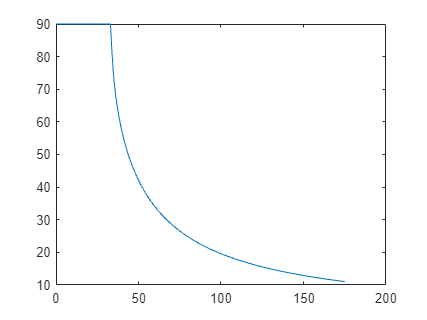

plot(r, rad2deg(phi));

## Find optial lift coefficient


syms C_Lopt 
assume(C_Lopt, ["real", "positive"]);
assumeAlso( (2*W2S./(rho*C_Lopt*r*g)) >= 0 );
assumeAlso( (2*W2S./(rho*C_Lopt*r*g)) <= 1);

eqn = 0 == C_D_0 - (C_Lopt^2) / (pi*A*e) - (V_c * C_Lopt^(3/2)) / (2 * sqrt((2/rho) * W2S));
for j = 1:4  
    for i = 1:length(V_c)
        C_L_computed = double(vpasolve(eqn(j,i),C_Lopt));
         C_L(j,i) = double(vpasolve(eqn(j,i),C_Lopt));
    end
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.


% Need to plot V_avg as function of A and W2S on 3D plot to get level
% curves
%[C_L,V_c,C_D0] = CLoptimum(L_Dmax, A, e, rho, r, g, W2S);% Haven't been able to get this function to work yet

V_avg = Vavgfsd(V_c, C_D_0, A, e, rho, W2S, C_L);

% for i = 1:4
%     plot(r,V_avg(i,:));
% end